# Figure D1: S_EI on SEE SElgn plains

clear

## 1. Select background parameters

CurrentFolder = pwd

CurrentFolder = '/home/lai-sang/Documents/GitHub/NYU-Vision/MFModel Code'

FigurePath = [CurrentFolder '/Figures'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
addpath([CurrentFolder '/HPCData/FigureD1b'])


S_EItest = linspace(0.08,0.20,21);%S_IItest = [0.08  0.12  0.16  0.20];


## 4. Extract contourline for different SII level

white frE = [3 5], frI/frE = (3, 4.25)

FrEContourLevel = [3,4,5];
conturcAll = cell(length(S_EItest), length(FrEContourLevel));
for S_EIInd = 1:length(S_EItest)
    S_EI = S_EItest(S_EIInd);
    
    CurrentPanelFile = sprintf('FigD1b_SEIInd%d.mat', S_EIInd);
    if isfile([CurrentFolder '/HPCData/FigureD1b/' CurrentPanelFile])
        load(CurrentPanelFile,'ContourData_7D')
    else
        fprintf('No Data for S_EI=%.3f\n',S_EI)
        continue
    end
    
    KerSize = 3;
    ConvMat = 1/KerSize^2*ones(KerSize);
    % First axis for fr
    CurrentBlowup = logical(squeeze(ContourData_7D.FailIndi(:,:)));% CurrentBlowup(1:35,1:283) = 1; CurrentBlowup = logical(CurrentBlowup);
    Currentsteady = squeeze(ContourData_7D.ConvIndi(:,:)); %Currentsteady(1:35,1:283) = true;
    
    CurrentFrE = squeeze(ContourData_7D.Fr_NoFix(1,:,: )); %CurrentFrE(CurrentFrE<eps) = nan;
    CurrentFrESm = FrRateModify(CurrentFrE, ConvMat,CurrentBlowup,Currentsteady);
    CurrentFrI = squeeze(ContourData_7D.Fr_NoFix(2,:,: ));
    CurrentFrISm = FrRateModify(CurrentFrI, ConvMat,CurrentBlowup,Currentsteady);
    
    CurrentFrEGA = CurrentFrESm; CurrentFrIGA = CurrentFrISm;
    CurrentFrEGA(~(CurrentFrESm>=2.5 & CurrentFrESm<=5.5 & ...
        CurrentFrISm./CurrentFrESm    >=2.85 & ...
        CurrentFrISm./CurrentFrESm    <=4.35)) = nan;
    CurrentFrIGA(~(CurrentFrESm>=2.5 & CurrentFrESm<=5.5 & ...
        CurrentFrISm./CurrentFrESm    >=2.85 & ...
        CurrentFrISm./CurrentFrESm    <=4.35)) = nan;
    
    [C,h]= contour(ContourData_7D.FreeParRan{5},ContourData_7D.FreeParRan{1},...
                       CurrentFrEGA, FrEContourLevel);
    Lvls = FrEContourLevel;
    idxc = cell(size(Lvls));
    Llen = cell(size(Lvls));
    for k1 = 1:length(Lvls)
        idxc{k1} = find(C(1,:) == Lvls(k1));
        Llen{k1} = C(2,idxc{k1});
        for SeqInd = 1:length(idxc{k1})
            conturcAll{S_EIInd,k1} = [conturcAll{S_EIInd,k1},...
                                      C(:,idxc{k1}(SeqInd)+1 : idxc{k1}(SeqInd)+1+Llen{k1}(SeqInd)-1)];
        end
        conturcAll{S_EIInd,k1} = [conturcAll{S_EIInd,k1}; 
                                  S_EI*ones(1,size(conturcAll{S_EIInd,k1},2))];
    end
    close all
    
end

Fig1 = figure('Name','FigD1','units','normalized','outerposition',[0 0 .80 1]);
%subplot 121
hold on
[xq, yq] = meshgrid(ContourData_7D.FreeParRan{5},ContourData_7D.FreeParRan{1});
k1 = 1;
LevelData = cell2mat(reshape(conturcAll(6:end,k1),1,length(S_EItest)-5));
vq = griddata(LevelData(1,:),LevelData(2,:),LevelData(3,:),...
              xq, yq);

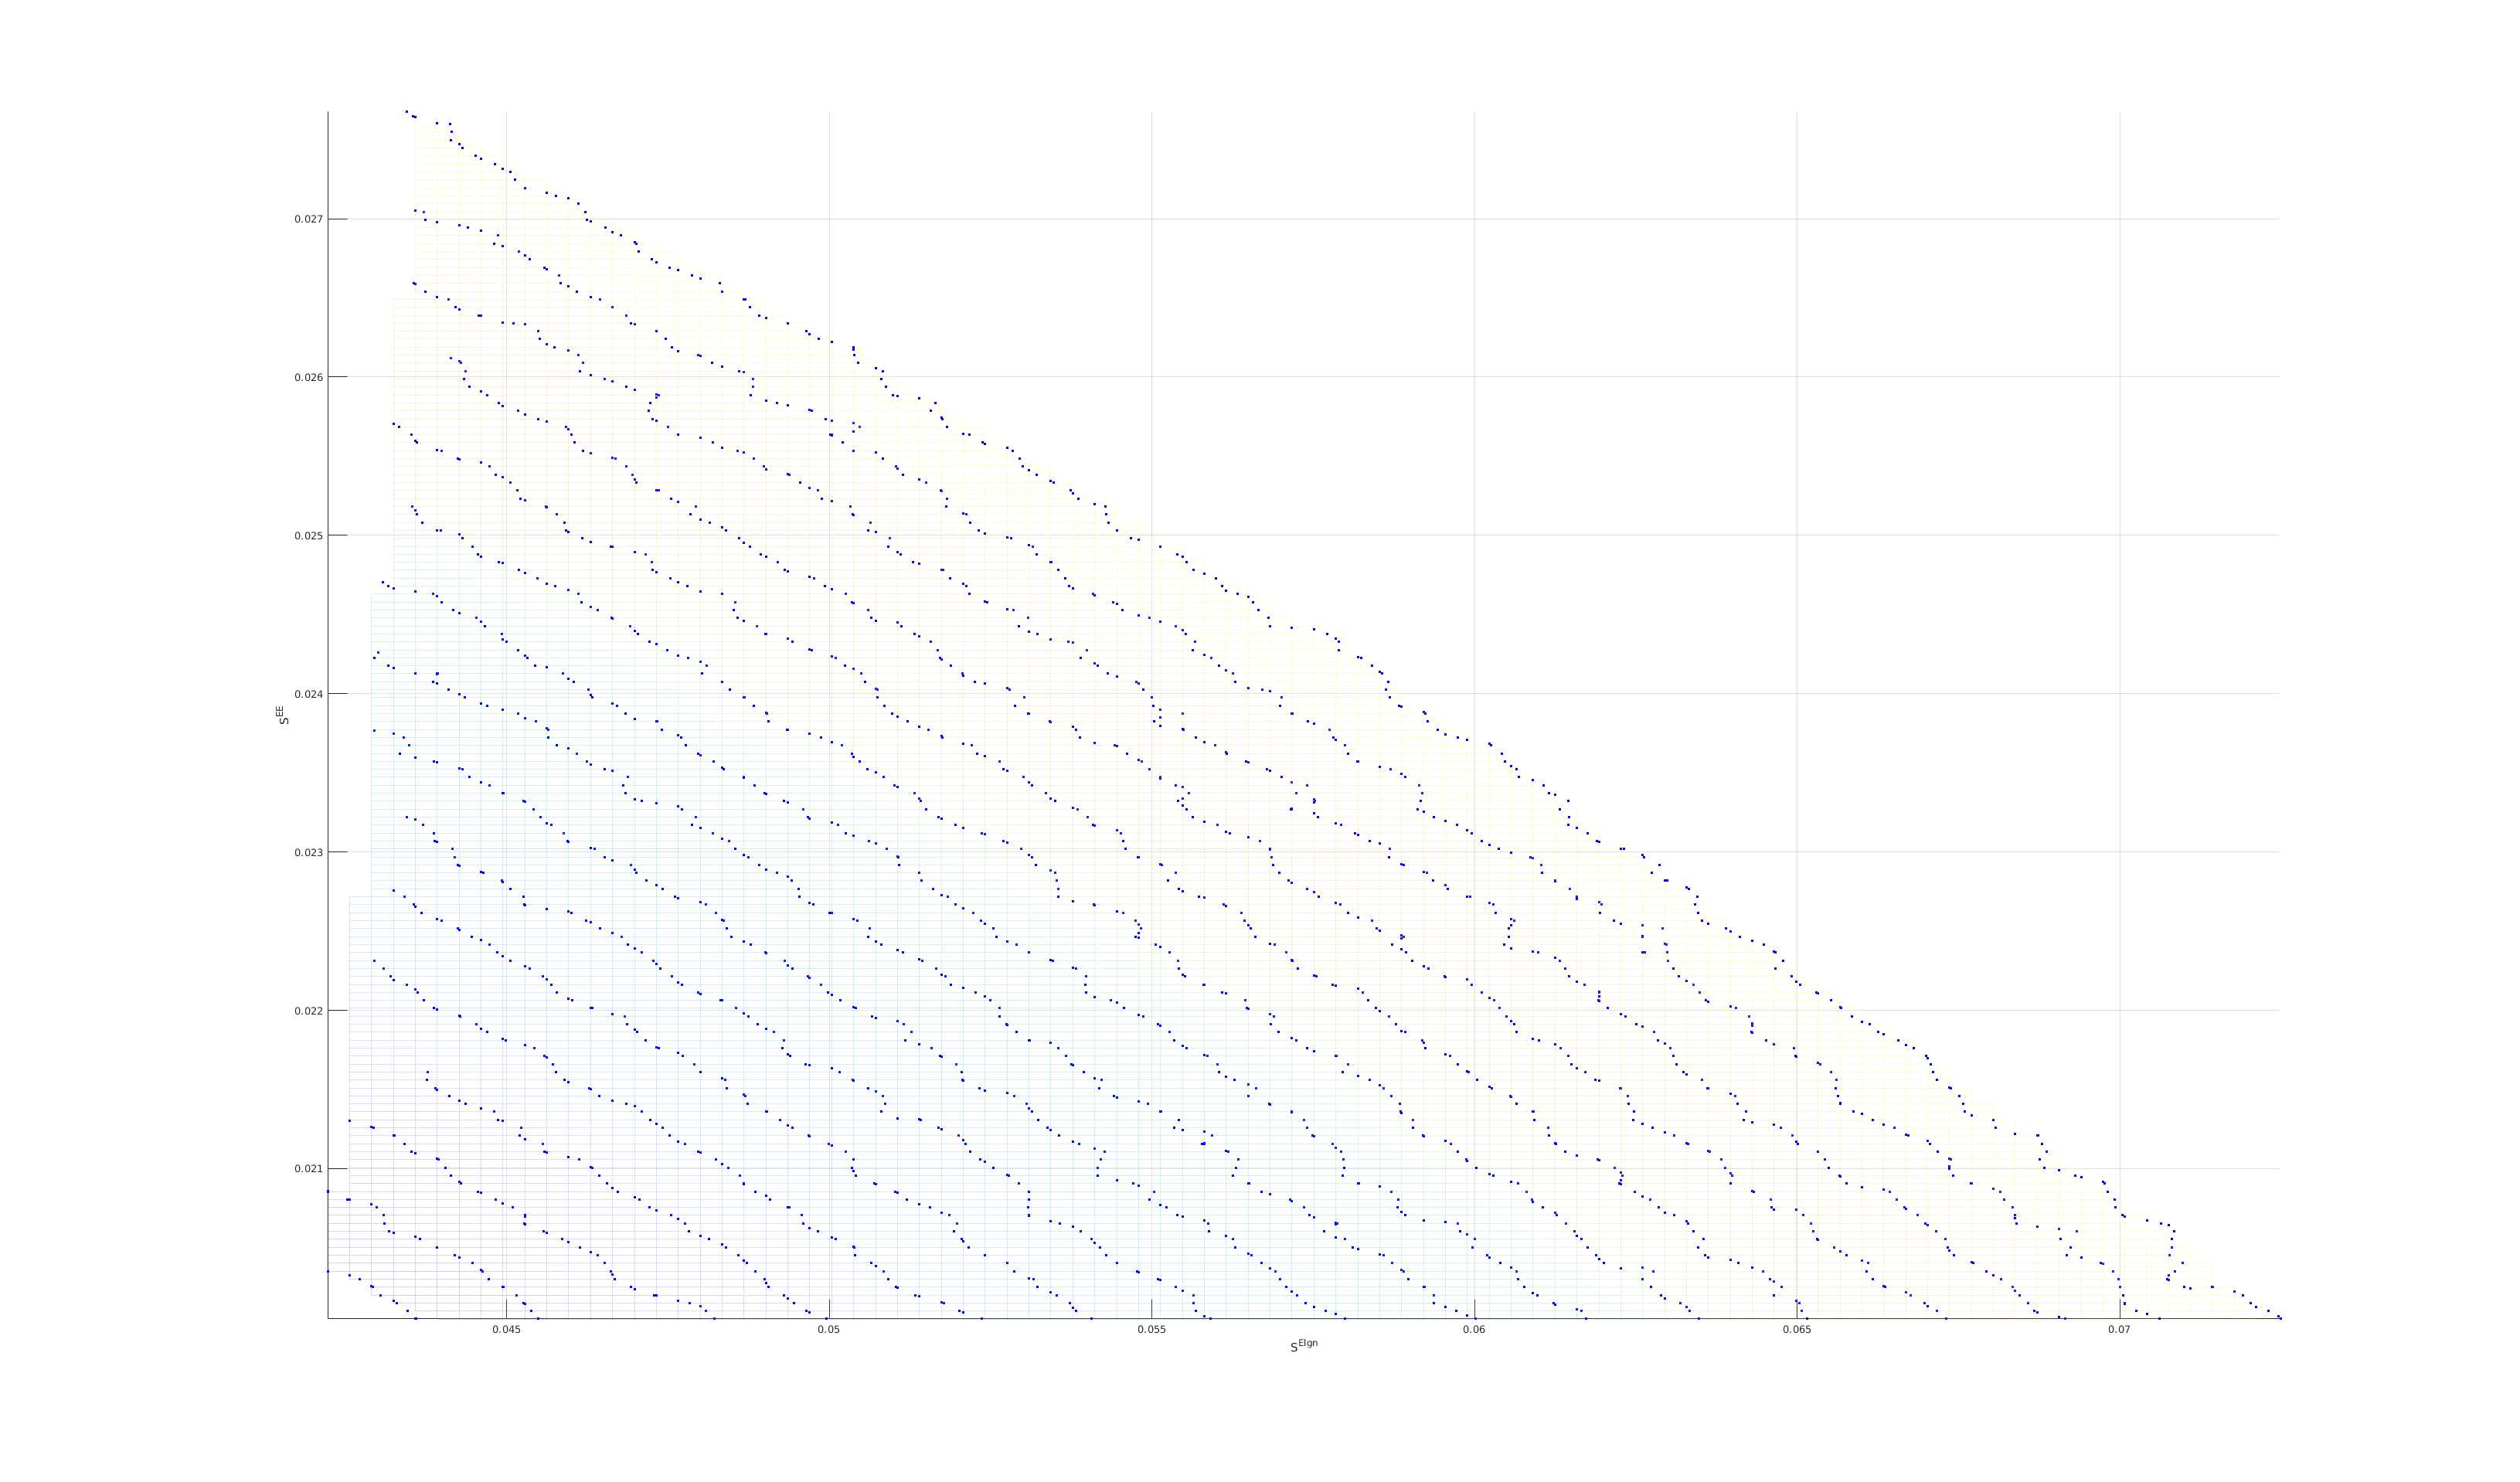

mesh(xq, yq, vq,'EdgeAlpha',0.2, 'FaceAlpha',0.1)
scatter3(LevelData(1,:),LevelData(2,:),LevelData(3,:),'b.')
xlabel('S^{Elgn}');ylabel('S^{EE}');zlabel('S^{EI}')
grid on
axis tight

Save figures

FigurePaperpath = [CurrentFolder '\Figure for Paper\'];
FigName1 = 'FigureD1';
savefig(Fig1,[FigurePaperpath FigName1 '.fig']);


Print Figs

Fig1.PaperUnits = 'centimeters';
Fig1.PaperSize = [40,28];
Fig1.PaperOrientation = "landscape";
exportgraphics(Fig1,[FigurePaperpath FigName1 '.pdf'],'Resolution',600)
